# 19 Intertrial Phase Clustering

The analytic signal resulting from time-frequency decomposition method, can be conceptualized as a vector in a complex polar plane with a magnitude and a phase angle. These phase angles provide information about the timing of frequency-band-specific activity and are the main focus of this chapter.

If you want to compute the consistency of time-domain EEG traces over trials, you need to form an event-related potential (ERP). Computing the consistency of time-frequency power over trials is the same as for ERPs. However, computing the consistency of time-frequency phase values over trials is not so simple because phase values cannot be averaged together in the same way that voltage values or power values can be averaged.

## 19.1 Why Phase Values Cannot Be Averaged

Phase angles are circular, which means that directly averaging their radian values as if they were normal linear numbers is inappropriate because values that appear numerically distant can actually represent nearly identical positions in polar space.

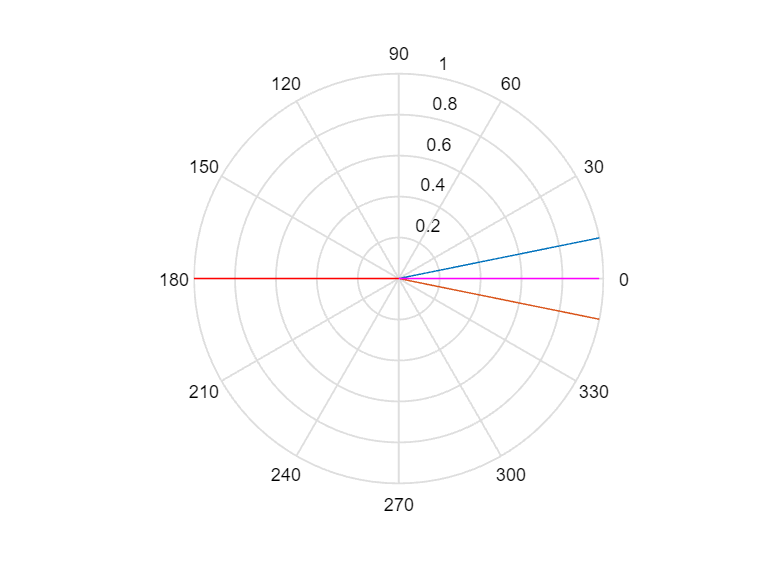

a = [0.2 2*pi-.2];

figure
polar([0 0; a],[0 0; 1 1])
hold on
polar([0 mean(a)],[0 1],'r')
polar([0 angle(mean(exp(1i*a)))],[0 abs(mean(exp(1i*a)))],'m')

**Figure 19.1 **

*Illustration of why averaging phase angle radian values is inappropriate.*

Remember that phase angles can be represented as vectors with unit length on a circle, and that Euler's formula ($e^{ik}$) provides a convenient mathematical description of those vectors in a complex plane. Thus, a population of phase angles can be represented as a population of vectors on a circle. The extent to which these vectors are clustered (or nonuniformly distributed) is the measure of phase clustering across trials. If the timing of an oscillatory process is the same or similar at each repetition of a stimulus or other experiment event, their phase angles should take on similar values across trials.

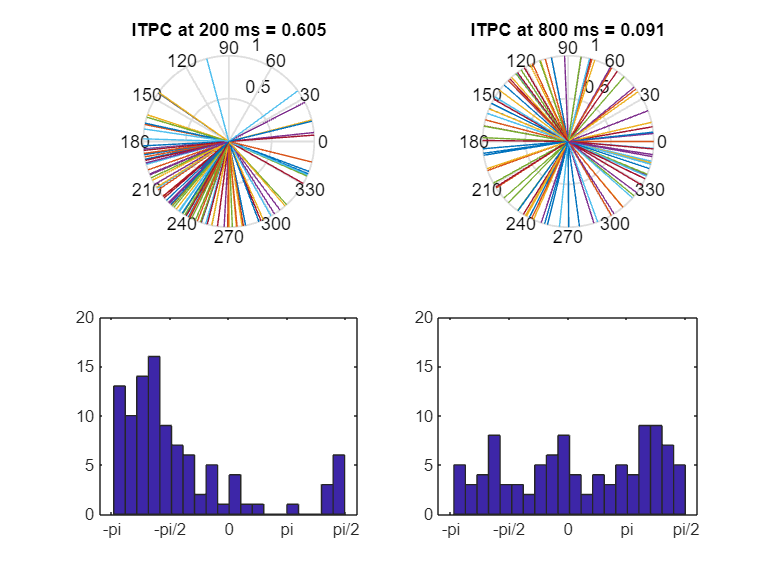

load sampleEEGdata

centerfreq = 12;
chan2plot  = 'pz';
times2plot = [ 200 800 ];

n_wavelet     = EEG.pnts;
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

time    = -EEG.pnts/EEG.srate/2:1/EEG.srate:EEG.pnts/EEG.srate/2-1/EEG.srate;
wavelet = exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*((4/(2*pi*centerfreq))^2)))/centerfreq;

eegfft = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
eegconv = eegconv(1:n_convolution);
eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);

% plot
figure
for subploti=1:2
    subplot(2,2,subploti)
    [junk,idx]=min(abs(EEG.times-times2plot(subploti)));
    polar([zeros(1,EEG.trials); angle(eegconv(idx,:))],[zeros(1,EEG.trials); ones(1,EEG.trials)])
    title([ 'ITPC at ' num2str(times2plot(subploti)) ' ms = ' num2str(round(1000*abs(mean(exp(1i*angle(eegconv(idx,:))))))/1000) ])
    
    subplot(2,2,subploti+2)
    hist(angle(eegconv(idx,:)),20)
    set(gca,'xlim',[-pi pi]*1.1,'xtick',-pi:pi/2:pi,'xticklabel',{'-pi';'-pi/2';'0';'pi';'pi/2'},'ylim',[0 20])
end

**Figure 19.2 **

*Phase-angle distributions at two time-frequency points.*

## 19.2 Intertrial Phase Clustering

The measure of phase angle clustering is called intertrial phase clustering (ITPC). ITPC measures the extent to which a distribution of phase angles at each time-frequency-electrode point across trials is nonuniformly distributed in polar space. In the literature you may see this measure referred to as: 

- Phase-locking value 

- Phase-locking factor 

- Phase resetting

- Phase coherence

- Intertrial phase coherence 

- Cross-trial or intertrial

the uniformity of the distribution of phase angles is measured by computing the average vector and then taking the length of that average vector. 

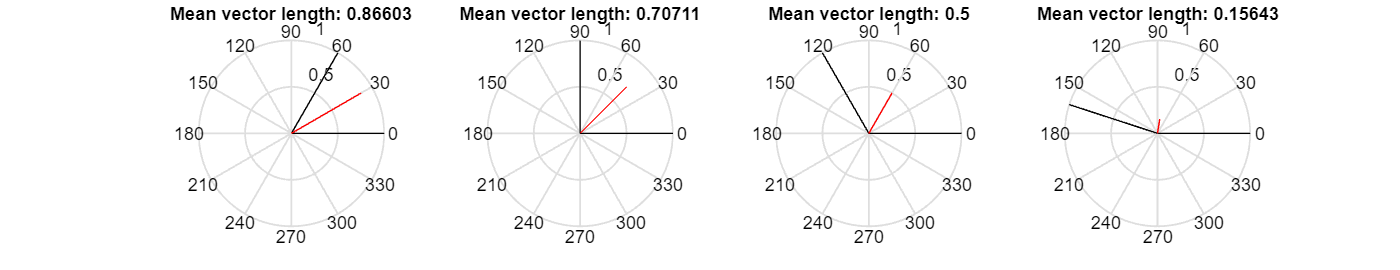

vectors{1} = [0 pi/3];
vectors{2} = [0 pi/2];
vectors{3} = [0 2*pi/3];
vectors{4} = [0 pi*.9];

figure(Position=[100,100,1300,250])
for i=1:length(vectors)
    subplot(1,length(vectors),i)
    
    polar([0 vectors{i}(1)],[0 1],'k')
    hold on
    polar([0 vectors{i}(2)],[0 1],'k')
    
    meanvect = mean(exp(1i*vectors{i}));
    polar([0 angle(meanvect)],[0 abs(meanvect)],'r')
    title([ 'Mean vector length: ' num2str(abs(meanvect)) ])
end

**Figure 19.3 **

Example pairs of unit-length vectors and their averages.

Note that the individual vectors always have unit length (length of 1.0), but the average vector has a length less than 1. The further apart the two vectors are from each other, the smaller the length of the average vector. Thus, the length of the average vector reflects the closeness of the two unit-length vectors. ITPC is this length.

ITPC is bound between zero and one, with zero indicating completely uniformly distributed phase angles and one indicating completely identical phase angles.

Remember, the formula follows from the polar notation of a complex number using Euler's formula:

### 
$$Me^{i\theta } =M\left\lbrack \cos \left(\theta \right)+\mathrm{isin}\left(\theta \right)\right\rbrack$$


ITPC mathematically quantified below:

### 
$$ITPC_{tf} =\left|n^{-1} \sum_{r=1}^n e^{ik_{tfr} } \right|$$


- $n$ is the number of trials

- $n^{-1}$ is a convenient shorthand for $1/n$, and, combined with the summation operator indicates an average

- The double vertical bars indicate the absolute value or, in this case, the length of the average vector

- $k$ is the phase angle in radians

- $r$ is the specific trial

- $tf$is thr time-frequency point

- $e^{ik}$ is from Euler's formula and provides the complex polar representation of a phase angle $k$ on trial $r$ at time-frequency point $tf$

You can see that the $M$ from Euler’s formula is not present in ITPC ones. This means that magnitude information is not taken into account when computing ITPC, and thus, the lengths of all vectors are implicitly set to 1.0. This formula can be expressed in Matlab code as:

- where `k` is a vector of phase angles at one time-frequency point over trials

Notice that this equation does not average phase angles in radians; it averages complex vectors whose angles are defined by the phase angles in radians.

The angle of the average vector is the average phase, or the "preferred" position of the angles at that time-frequency point over trials. In practice, the average phase angle is not often used. However, it would be possible for two experimental conditions to elicit comparable ITPC strength but significant differences in the preferred phase angle.

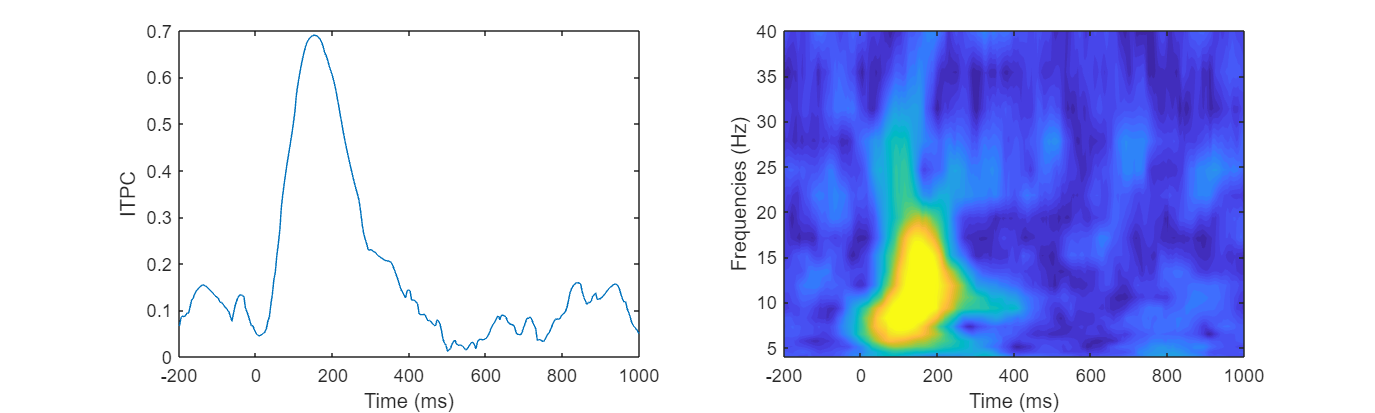

chan2plot  = 'pz';
centerfreq = 12;
eegfft = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

% ITPC at one frequency band
wavelet = exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*((4/(2*pi*centerfreq))^2)))/centerfreq;
% convolution
eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
eegconv = eegconv(1:n_convolution);
eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);

figure(Position=[100,100,1000,300])

subplot(121)
plot(EEG.times,abs(mean(exp(1i*angle(eegconv)),2)))
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)')
ylabel('ITPC')


frequencies = logspace(log10(4),log10(40),20);
s = logspace(log10(3),log10(10),length(frequencies))./(2*pi*frequencies);
itpc = zeros(length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*(s(fi)^2)))/frequencies(fi);
    
    eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
    eegconv = eegconv(1:n_convolution);
    eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);
    
    itpc(fi,:) = abs(mean(exp(1i*angle(eegconv)),2));
end

subplot(122)
contourf(EEG.times,frequencies,itpc,40,'linecolor','none')
set(gca,'clim',[0 .6],'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('Frequencies (Hz)')

**Figure 19.4 **

*ITPC from electrode Pz at 12 Hz and over time-frequency space.*

## 19.3 Strength in Numbers

Trial count influences ITPC. Because ITPC cannot be below zero, noise and sampling errors are more likely to increase rather than decrease ITPC, particularly when there are few trials.

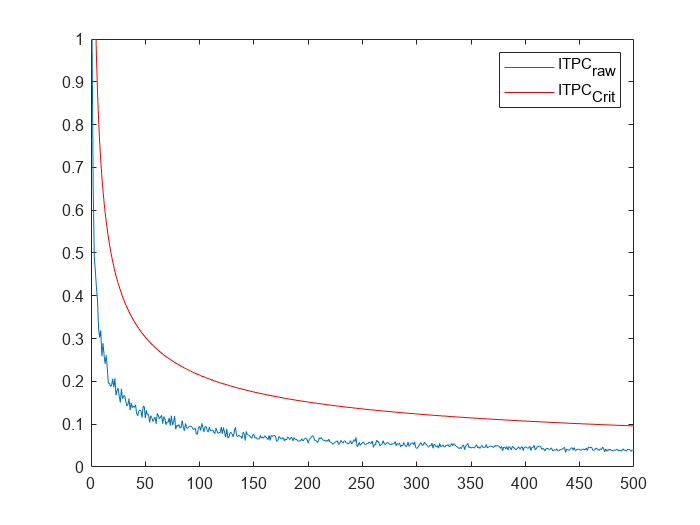

n_trials    = 500;
itpcByNFake = zeros(1,n_trials);

for n=1:n_trials
    for iteri=1:50
        itpcByNFake(n) = itpcByNFake(n) + abs(mean(exp(1i*(rand(1,n)*2*pi-pi))));
    end
end
itpcByNFake = itpcByNFake./iteri;

itpcByNFakeZ = (1:n_trials).*(itpcByNFake.^2);
itpcByNFakeP = exp(sqrt(1+4.*(1:n_trials)+4*( ((1:n_trials).^2) - ((1:n_trials).*itpcByNFake).^2))-(1+2*(1:n_trials)));
itpcFakeCrit = sqrt( -log(.01)./(1:n_trials) );

figure
plot(1:n_trials,itpcByNFake)
hold on
plot(1:n_trials,itpcFakeCrit,'r')
set(gca,'ylim',[0 1])
legend({'ITPC_r_a_w';'ITPC_C_r_i_t'})

**Figure 19.5 **

*ITPC as a function of trial count for simulated random phase angles averaged over 50 simulations. Also shown is the critical ITPC value for each trial count, corresponding to a p-value threshold of 0.01.*

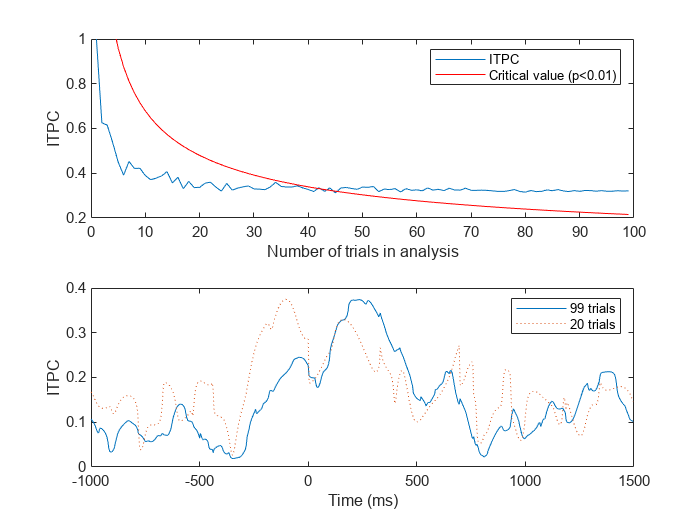

centerfreq = 6;
chan2plot  = 'fcz';

n_wavelet     = EEG.pnts;
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

time    = -EEG.pnts/EEG.srate/2:1/EEG.srate:EEG.pnts/EEG.srate/2-1/EEG.srate;
wavelet = exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*((4/(2*pi*centerfreq))^2)))/centerfreq;

eegfft  = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
eegconv = eegconv(1:n_convolution);
eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);

figure

itpcByN = zeros(1,EEG.trials);
for n=1:EEG.trials
    for iteri=1:50
        trials2use  = randsample(EEG.trials,n);
        itpcByN(n)  = itpcByN(n) + mean(abs(mean(exp(1i*angle(eegconv(282:372,trials2use))),2)),1);
    end
end
itpcByN = itpcByN./iteri;

itpcByNZ = (1:EEG.trials).*(itpcByN.^2);
itpcByNP = exp(sqrt(1+4.*(1:EEG.trials)+4*( ((1:EEG.trials).^2) - ((1:EEG.trials).*itpcByN).^2))-(1+2*(1:EEG.trials)));
itpcCrit = sqrt( -log(.01)./(1:EEG.trials) );

subplot(211)
plot(itpcByN)
hold on
plot(itpcCrit,'r')
xlabel('Number of trials in analysis')
ylabel('ITPC')
set(gca,'ylim',[.2 1])
legend({'ITPC'; 'Critical value (p<0.01)'})

subplot(212)
plot(EEG.times,abs(mean(exp(1i*angle(eegconv)),2)))
hold on
randomtrials2plot = randperm(EEG.trials); % could also use randsamp if you have the stats toolbox
plot(EEG.times,abs(mean(exp(1i*angle(eegconv(:,randomtrials2plot(1:20)))),2)),':')
xlabel('Time (ms)'), ylabel('ITPC')
legend({'99 trials';'20 trials'})

**Figure 19.6 **

*Relationship between ITPC and trial count in real data.*

The effect of trial count on ITPC depends on the frequency.

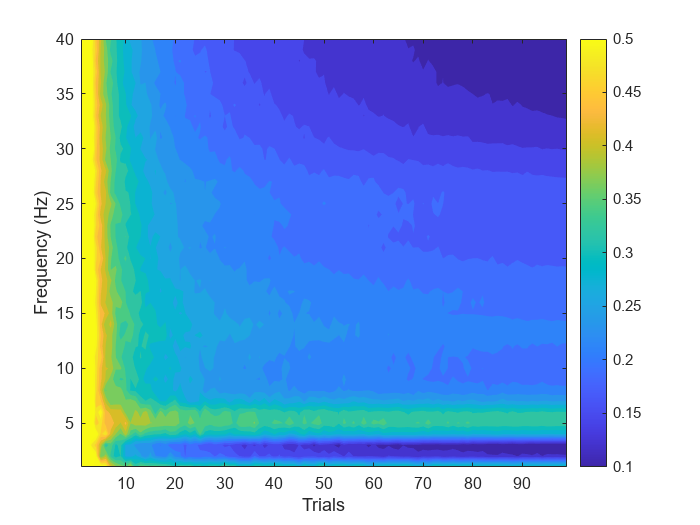

frequencies = 1:40;

niterations = 50;

itpcByNandF = zeros(length(frequencies),EEG.trials);

for fi=1:length(frequencies)
    
    centerfreq = frequencies(fi);
    
    wavelet = exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*((4/(2*pi*centerfreq))^2)))/centerfreq;
    
    eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
    eegconv = eegconv(1:n_convolution);
    eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);
    
    for n=1:EEG.trials
        for iteri=1:niterations
            trials2use  = randsample(EEG.trials,n);
            itpcByNandF(fi,n)  = itpcByNandF(fi,n) + mean(abs(mean(exp(1i*angle(eegconv(282:372,trials2use))),2)),1);
        end
    end
end

figure
contourf(1:EEG.trials,frequencies,itpcByNandF./iteri,40,'linecolor','none')
colorbar
set(gca,'clim',[.1 .5])
xlabel('Trials')
ylabel('Frequency (Hz)')

**Figure 19.7 **

*ITPC as a function of trial count and frequency.*

Low trial count can be more deleterious when ITPC is compared between conditions that differ in trial count.

## 19.4 Using ITPC When There Are Few Trials or Condition Differences in Trial Count

If you have differences in trial count across conditions and would like to compare condition differences in ITPC, there are three strategies you can apply:

- Match conditions for trial count within subject.

- Apply a condition-specific baseline subtraction or percentage change transformation. However, low trial count not only increases ITPC, it also increases the susceptibility of ITPC to noise or nonrepresentative data.

- Transform the ITPC to ITPCz, also known as Rayleigh's Z. 

The formula for ITPCz follows:

### 
$$ITPC_Z =n\times ITPC^2$$


- $n$ is the number of trials. 

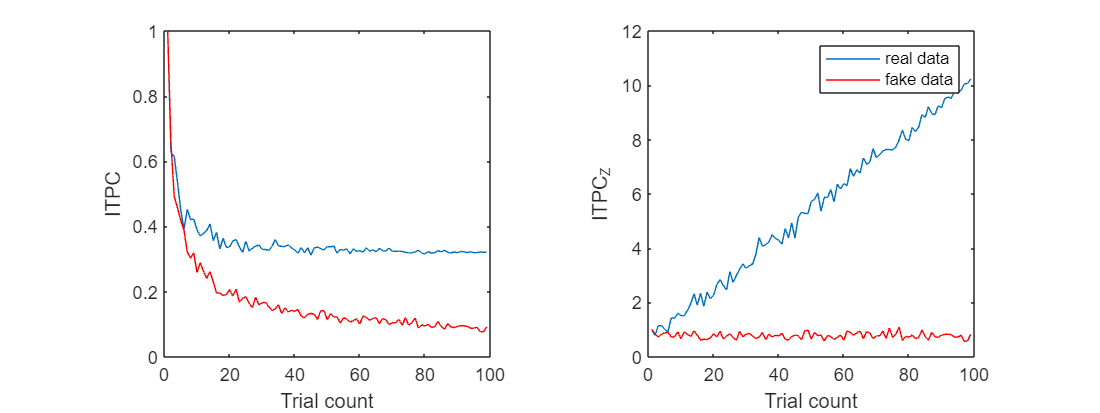

figure(Position=[100,100,800,300])

set(gcf,'name','Rayleigh''s Z')
subplot(121)
plot(itpcByN)
hold on
plot(itpcByNFake(1:99),'r')
xlabel('Trial count'), ylabel('ITPC')
axis square

subplot(122)
plot(itpcByNZ)
hold on
plot(itpcByNFakeZ(1:99),'r')
xlabel('Trial count'), ylabel('ITPC_Z')
legend({'real data';'fake data'})
axis square

**Figure 19.8 **

*Comparison of ITPC and ITPCz for randomly generated phase angles and real data. *

## 19.5 Effects of Temporal Jitter on ITPC and Power

Because ITPC reflects the precise timing of band-specific activity, it is sensitive to temporal jitter or temporal uncertainty of experiment events. The negative impact of temporal jitter becomes worse at higher frequencies because the cycles become shorter. Phase values are more temporally precise measurements of frequency-band-specific activity compared to power values.

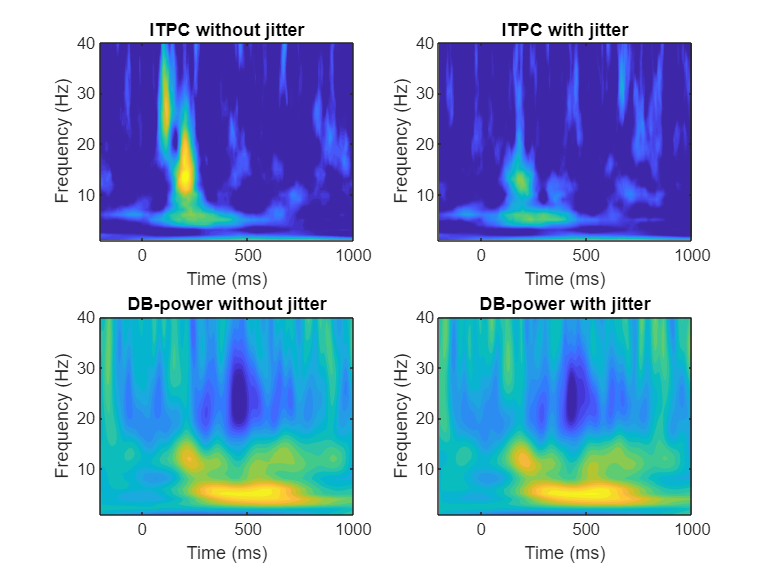

chan2plot   = 'fcz';
frequencies = 1:40;

time          = -EEG.pnts/EEG.srate/2:1/EEG.srate:EEG.pnts/EEG.srate/2-1/EEG.srate;
n_wavelet     = EEG.pnts;
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

plotlegends={'without jitter';'with jitter'};

figure

baselinetime = [ -300 -100 ];
baseidx=dsearchn(EEG.times',baselinetime(1)):dsearchn(EEG.times',baselinetime(2));

for simuli=1:2
    
    tempdat = squeeze(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:));
    for ti=1:size(tempdat,2)
        timejitter = ceil(rand*10)*(simuli-1); % (when simuli==1, timejitter==0)
        tempdat(:,ti) = tempdat([ timejitter+1:end 1:timejitter ],ti);
    end
    
    eegfft = fft(reshape(tempdat,1,[]),n_conv_pow2);
    
    itpc = zeros(length(frequencies),EEG.pnts);
    powr = zeros(length(frequencies),EEG.pnts);
    
    for fi=1:length(frequencies)
        
        centerfreq = frequencies(fi);
        
        wavelet = exp(2*1i*pi*centerfreq.*time) .* exp(-time.^2./(2*((4/(2*pi*centerfreq))^2)))/centerfreq;
        
        eegconv = ifft(fft(wavelet,n_conv_pow2).*eegfft);
        eegconv = eegconv(1:n_convolution);
        eegconv = reshape(eegconv(floor((EEG.pnts-1)/2):end-1-ceil((EEG.pnts-1)/2)),EEG.pnts,EEG.trials);
        
        itpc(fi,:) = abs(mean(exp(1i*angle(eegconv)),2));
        powr(fi,:) = mean(abs(eegconv).^2,2);
        powr(fi,:) = 10*log10(powr(fi,:)./mean(powr(fi,baseidx),2));
    end
    
    subplot(2,2,simuli)
    contourf(EEG.times,frequencies,itpc,40,'linecolor','none')
    set(gca,'clim',[.1 .5],'xlim',[-200 1000])
    xlabel('Time (ms)')
    ylabel('Frequency (Hz)')
    title([ 'ITPC ' plotlegends{simuli} ])
    
    subplot(2,2,simuli+2)
    contourf(EEG.times,frequencies,powr,40,'linecolor','none')
    set(gca,'clim',[-3 3],'xlim',[-200 1000])
    xlabel('Time (ms)')
    ylabel('Frequency (Hz)')
    title([ 'DB-power ' plotlegends{simuli} ])
end

**Figure 19.9**

*Temporal jitters of less than 40 ms can have deleterious effects on ITPC (top row), particularly at frequencies above 10 Hz. In contrast, temporal jitters have little noticeable effects on power.*

## 19.6 ITPC and Power

Phase angles are independent of power except in situations of very low power. The issue is that with decreasing power, phase becomes more difficult to estimate. Decreased power may nonetheless affect the signal-to-noise ratio of phase estimates, and so ITPC may in fact be affected by power.

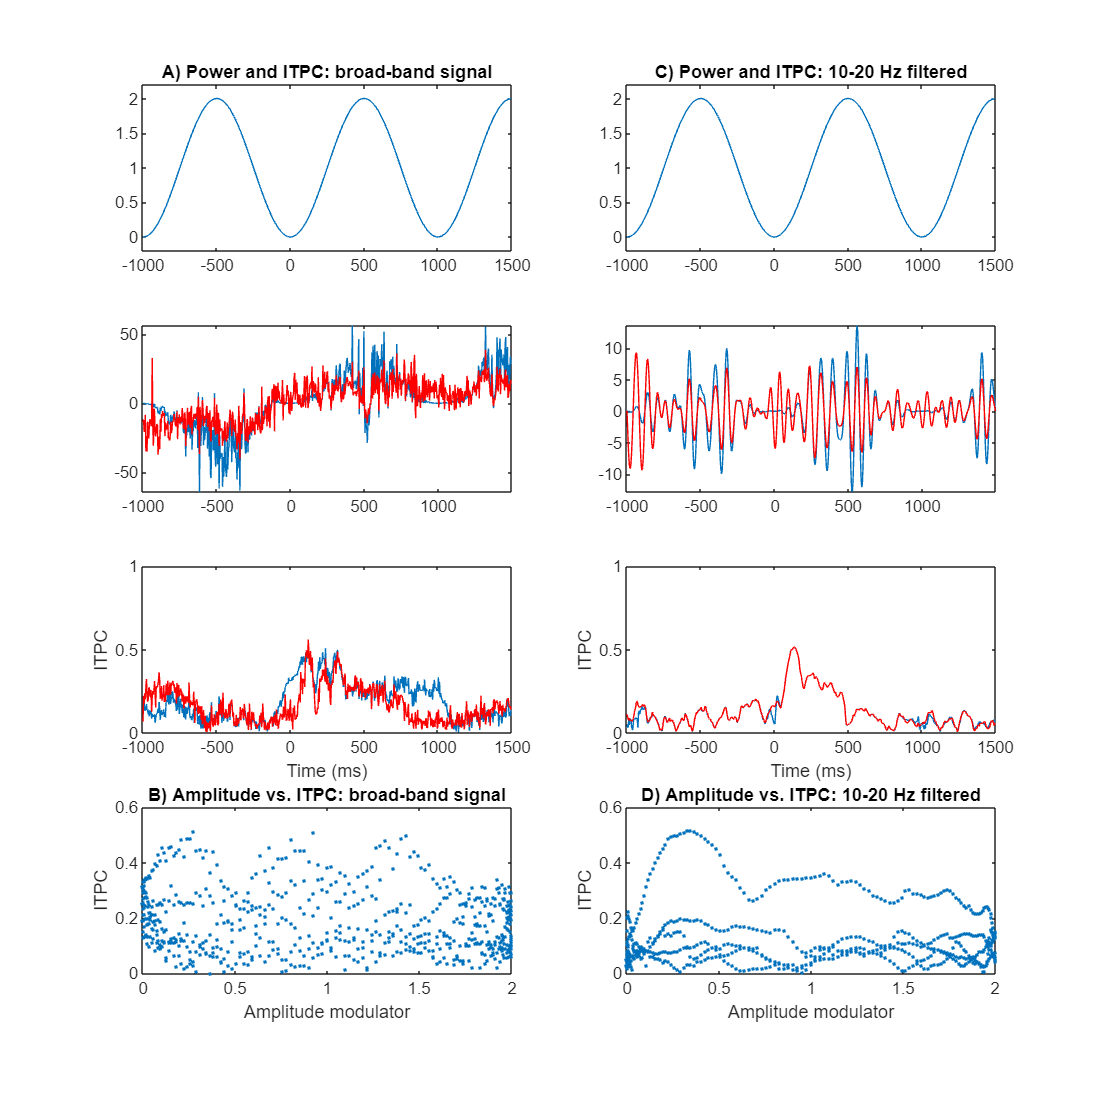

sensor2use = 'p7';
time = -EEG.pnts/EEG.srate/2:1/EEG.srate:EEG.pnts/EEG.srate/2-1/EEG.srate;
amp_mod = (sin(2*pi*1.*time)+2)-1;

data4test_bb = zeros(2,length(time),EEG.trials);
data4test_bp = zeros(2,length(time),EEG.trials);

for triali=1:EEG.trials
    trialdata_bb = double(EEG.data(strcmpi(sensor2use,{EEG.chanlocs.labels}),:,triali));
    trialdata_bp = bandpass(trialdata_bb, [10 20], EEG.srate);
    
    data4test_bb(1,:,triali) = trialdata_bb .* amp_mod;
    data4test_bb(2,:,triali) = trialdata_bb;
    
    data4test_bp(1,:,triali) = trialdata_bp .* amp_mod;
    data4test_bp(2,:,triali) = trialdata_bp;
end

itpc_mod_bb   = squeeze(abs(mean(exp(1i*angle(hilbert(data4test_bb(1,:,:)))),3)));
itpc_nomod_bb = squeeze(abs(mean(exp(1i*angle(hilbert(data4test_bb(2,:,:)))),3)));
itpc_mod_bp   = squeeze(abs(mean(exp(1i*angle(hilbert(data4test_bp(1,:,:)))),3)));
itpc_nomod_bp = squeeze(abs(mean(exp(1i*angle(hilbert(data4test_bp(2,:,:)))),3)));

figure(Position=[100,100,1000,1000])

subplot(4,2,1)
plot(EEG.times, amp_mod)
set(gca,'ylim',[-.2 2.2])
title('A) Power and ITPC: broad-band signal')

subplot(4,2,3)
plot(EEG.times, squeeze(data4test_bb(1,:,10)))
hold on
plot(EEG.times, squeeze(data4test_bb(2,:,10)), 'r')
axis tight

subplot(4,2,5)
plot(EEG.times, itpc_mod_bb)
hold on
plot(EEG.times, itpc_nomod_bb, 'r')
set(gca,'ylim',[0 1])
xlabel('Time (ms)'), ylabel('ITPC')

subplot(4,2,7)
plot(amp_mod, itpc_mod_bb, '.')
xlabel('Amplitude modulator'), ylabel('ITPC')
title('B) Amplitude vs. ITPC: broad-band signal')

subplot(4,2,2)
plot(EEG.times, amp_mod)
set(gca,'ylim',[-.2 2.2])
title('C) Power and ITPC: 10-20 Hz filtered')

subplot(4,2,4)
plot(EEG.times, squeeze(data4test_bp(1,:,10)))
hold on
plot(EEG.times, squeeze(data4test_bp(2,:,10)), 'r')
axis tight

subplot(4,2,6)
plot(EEG.times, itpc_mod_bp)
hold on
plot(EEG.times, itpc_nomod_bp, 'r')
set(gca,'ylim',[0 1])
xlabel('Time (ms)'), ylabel('ITPC')

subplot(4,2,8)
plot(amp_mod, itpc_mod_bp, '.')
xlabel('Amplitude modulator'), ylabel('ITPC')
title('D) Amplitude vs. ITPC: 10-20 Hz filtered')

**Figure 19.10 **

*The relationship between power and ITPC.*

The negative effect of very low power on ITPC was observed only in broadband signals; the amplitude of the data had relatively little impact on the ITPC of bandpass-filtered data. This is because the time periods of zero power were relatively brief and because the phase values at each time point of a wavelet convolution could still be estimated from surrounding points (because stationarity is assumed during the wavelet period). Thus, longer periods of sustained zero (or near-zero) power might hinder estimation of frequency-band-specific phase values. For all nonzero points of the amplitude modulator period, power modulation had no effect on ITPC. Thus, changes in power within realistic ranges of EEG data do not necessarily lead to spurious inflations or deflations of ITPC except in the unusual case when power is exactly zero for an extended period of time.

In general, these findings suggest that power and ITPC are not necessarily coupled and that ITPC can be safely interpreted independently of power. Nonetheless, the potential relationship between power and ITPC should not be dismissed because of this one illustration. It is a good idea to examine the relationship between ITPC and power in your data before confidently interpreting ITPC and power in different ways. This could be done, for example, by showing qualitative differences between power and ITPC over time, frequency, electrodes, or conditions.

## 19.7 Weighted ITPC

Weighted ITPC (wITPC) is an extension of ITPC that provides a more direct link between phase angles and trial-varying behavior or experiment parameters. The wITPC addresses two limitations of interpreting ITPC with respect to cognitive processes:

- ITPC can arise due to several task-related but not condition-specific factors. 

- ITPC precludes discovery of phase dynamics that are related to the task but are not clustered within the same range across trials.

With wITPC the magnitude of each vector is scaled according to a behavioral or experiment variable on that trial:

### 
$$wITPC_{tf} =\left|n^{-1} \sum_{r=1}^n b_r e^{ik_{tfr} } \right|$$


- $b$ is a variable that is unique to trial $r$

Thus, the lengths of the vectors are modulated by $b$ rather than having unit length. This vector b might need to be scaled if it contains negative numbers because vectors should have positive length.

While introducing the behavioral weighting variable ($b$) successfully solves the first limitation by linking phase directly to a specific behavior rather than general task-evoked responses, the raw wITPC formula still suffers from two major problems:

- The raw wITPC score is still artificially inflated by periods of strong overall phase clustering (regular ITPC).

- Because the vector length is now multiplied by the magnitude od $b$, wITPC loses its clean 0-to-1 boundary. Its magnitude becomes completely arbitrary depending on the scale of your data.

The solution is to use nonparametric permutation testing. This resolves both the b-scaling issue and the phase-clustering issue. Nonparametric permutation testing has an additional advantage, which is that it transforms the wITPC to a value that is amenable to within- and across-subject statistical evaluation and comparison. Here is the step-by-step algorithm to compute wITPCz with nonparametric permutation testing:

- Calculate the true wITPC using the actual, un-shuffled pairing between the trial phase angles and the behavioral variable bbb.

- Randomly shuffle the order of the $b$ values across trials to break their true relationship with the phase angles.

- Calculate a new "null hypothesis" wITPC using these randomly mismatched $b$ values.

- Repeat steps 2 and 3 many times to generate a large distribution of null wITPC values.

- Subtract the mean of the null distribution from your observed wITPC, and divide that result by the standard deviation of the null distribution.

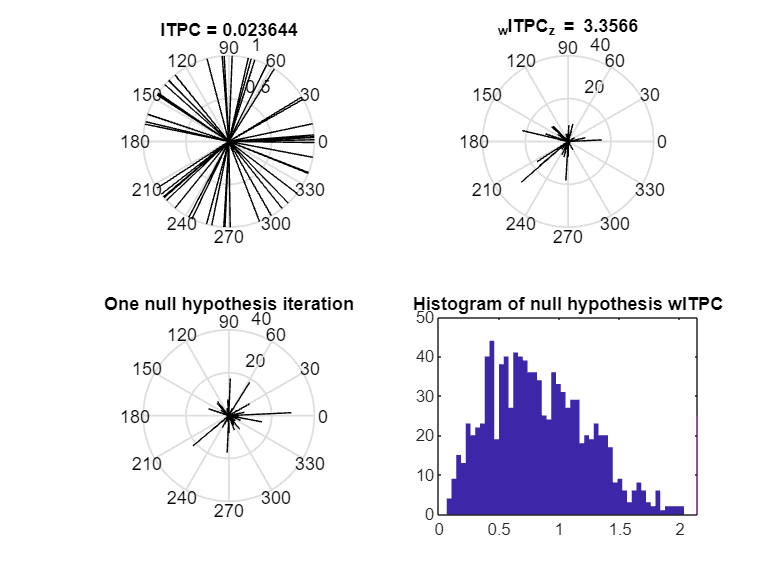

randvects = rand(50,1)*2*pi-pi;
vectormod = (randvects + randn(size(randvects))).^2;
vectormod2 = vectormod-min(vectormod)+1;


figure

subplot(221)
polar([zeros(size(randvects)) randvects]',[zeros(size(randvects)) ones(size(randvects))]','k')
title([ 'ITPC = ' num2str(abs(mean(exp(1i*randvects)))) ])

subplot(222)
polar([zeros(size(randvects)) randvects]',[zeros(size(randvects)) vectormod]','k')

witpc = abs(mean(vectormod.*exp(1i*randvects)));
perm_witpc = zeros(1,1000);

for i=1:1000
    perm_witpc(i) = abs(mean(vectormod(randperm(length(vectormod))).*exp(1i*randvects)));
end

witpc_z = (witpc-mean(perm_witpc))./std(perm_witpc);
title([ '_wITPC_z = ' num2str(witpc_z) ])

subplot(223)
polar([zeros(size(randvects)) randvects]',[zeros(size(randvects)) vectormod(randperm(length(vectormod)))]','k')
title('One null hypothesis iteration')

subplot(224)
[y,x]=hist(perm_witpc,50);
h=bar(x,y,'histc');
set(h,'linestyle','none')
hold on
plot([witpc witpc],get(gca,'ylim')/2,'m')
title('Histogram of null hypothesis wITPC')

**Figure 19.11 **

*Illustration of the procedure to compute wITPCz from wITPC in stimulated data.*

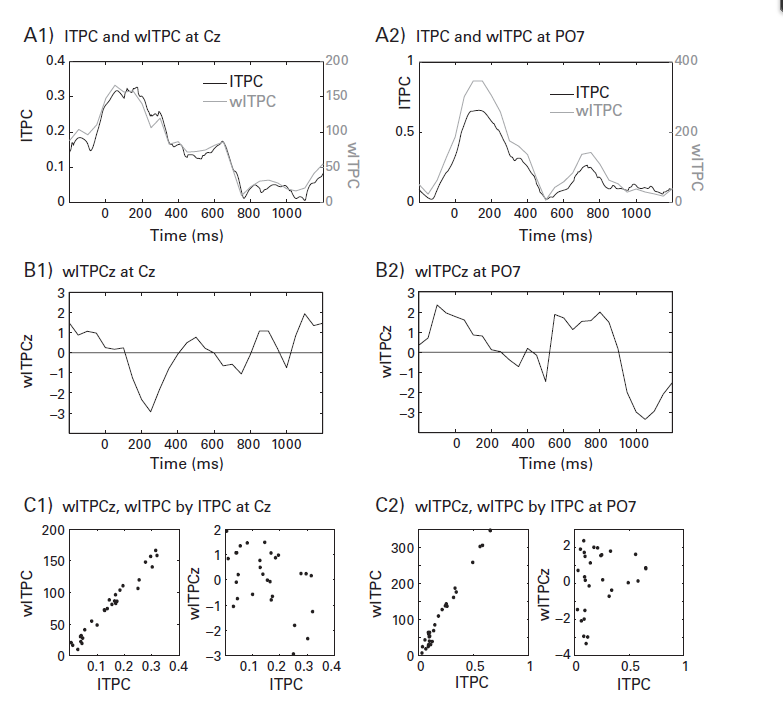

**Figure 19.12 **

*Comparison of wITPC and wITPCz with ITPC at electrodes Cz (left-hand plots) and PO7 (right-hand plots) for 6-Hz phase angles. The trial-varying modulating variable was reaction time.*

ITPC and wITPCz are complementary and provide different kinds of information regarding neurocognitive processing: 

- ITPC provides insights into the overall stimulus- or response-related timing of frequency-band-specific activity over trials and could be driven by a number of cognitive factors, some of which might have little relevance to the purpose of the experiment. 

- The wITPCz is specific to the behavior or experiment feature used as the $b$ weighting vector and is not related to phase clustering by itself.

## 19.8 Multimodal Phase Distributions

ITPC is designed for unimodal distributions—that is, phase distributions that have one peak. If there are multiple peaks, ITPC will be reduced (because it will reflect the average of two peaks) and will tend toward zero if the two peaks have opposite preferred phase angles. It is unknown how often bimodal (or multimodal) phase distributions occur in the brain or in the literature because they are rarely examined. There are methods for detecting and quantifying multimodal peaks in phase distributions: 

- Comparing the shape of the phase angle distribution to a null-hypothesis distribution.

- Using phase bifurcation to test for divergence of ITPC strength over two conditions.

- Computing ITPC separately for an arbitrary number of sub-bins and then examining differences in preferred angle.

## 19.9 Spike-Field Coherence

If you have single-unit and local field potential activity simultaneously recorded, you can compute spike-field coherence using a similar method as for ITPC: for each frequency band, identify the phase angle of the field potential at which the spike occurs and generate a distribution of phase angles according to spike times.

## 19.10 Describing This Analysis in Your Methods Section

Although ITPC is a mathematically standard formula, some of the terminology issues mentioned earlier can make it confusing. The best way to describe this measure is using an equation. The wITPCz is not a commonly used technique, so it should be explained in more detail, including how the distribution of wITPC values under the null hypothesis was generated.